
numG = [0.25];
denG = [1, 0.4, 0.25];
G = tf(numG, denG);


Kp = 15;     
Ki = 0.1;     
Kd = 50.3;      

numC = [Kd, Kp, Ki];
denC = [1, 0];
C = tf(numC, denC)


C =
 
  50.3 s^2 + 15 s + 0.1
  ---------------------
            s
 
Continuous-time transfer function.


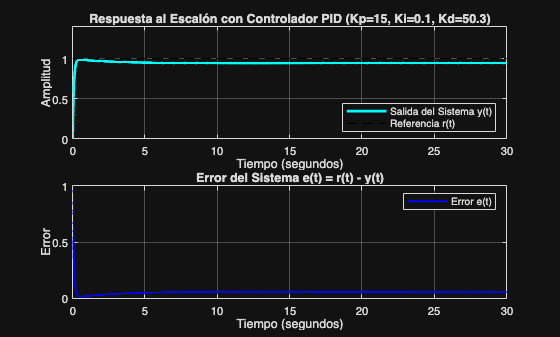


T = feedback(C * G, 1);


t = 0:0.01:30; 
[y, ~] = step(T, t); 


r = ones(size(y)); 


error = r - y;

figure; 
subplot(2, 1, 1); 
plot(t, y, 'c-', 'LineWidth', 2);
hold on;
plot(t, r, 'k--', 'LineWidth', 1); 
grid on;
title(['Respuesta al Escalón con Controlador PID (Kp=', num2str(Kp), ', Ki=', num2str(Ki), ', Kd=', num2str(Kd), ')']);
ylabel('Amplitud');
xlabel('Tiempo (segundos)');
legend('Salida del Sistema y(t)', 'Referencia r(t)', 'Location', 'SouthEast');
ylim([0, 1.4]);
subplot(2, 1, 2); 
plot(t, error, 'b-', 'LineWidth', 1.5);
grid on;
title('Error del Sistema e(t) = r(t) - y(t)');
ylabel('Error');
xlabel('Tiempo (segundos)');
legend('Error e(t)');



disp('Función de transferencia del controlador PID C(s):')

Función de transferencia del controlador PID C(s):


C


C =
 
  50.3 s^2 + 15 s + 0.1
  ---------------------
            s
 
Continuous-time transfer function.


disp('Función de transferencia del sistema controlado T(s):')

Función de transferencia del sistema controlado T(s):


T


T =
 
   12.57 s^2 + 3.75 s + 0.025
  -----------------------------
  s^3 + 12.97 s^2 + 4 s + 0.025
 
Continuous-time transfer function.


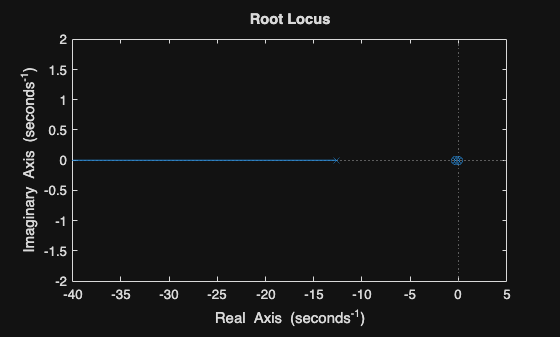

figure;
rlocus(T)